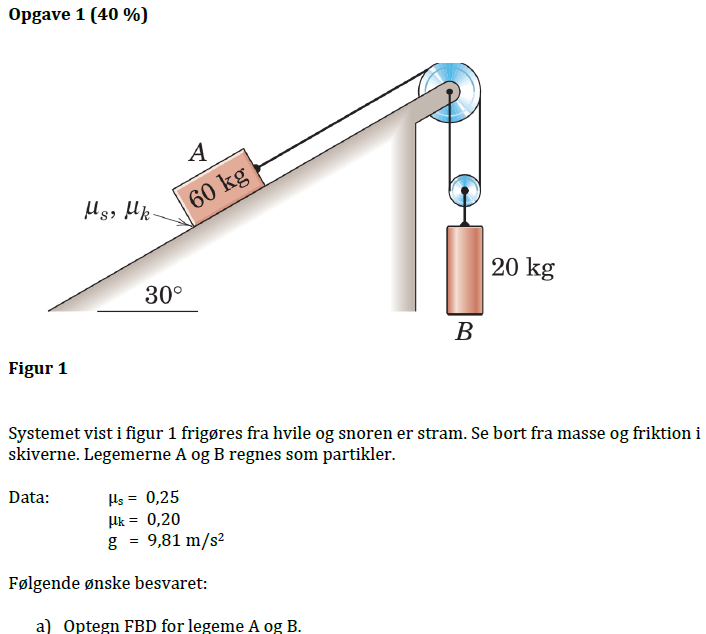

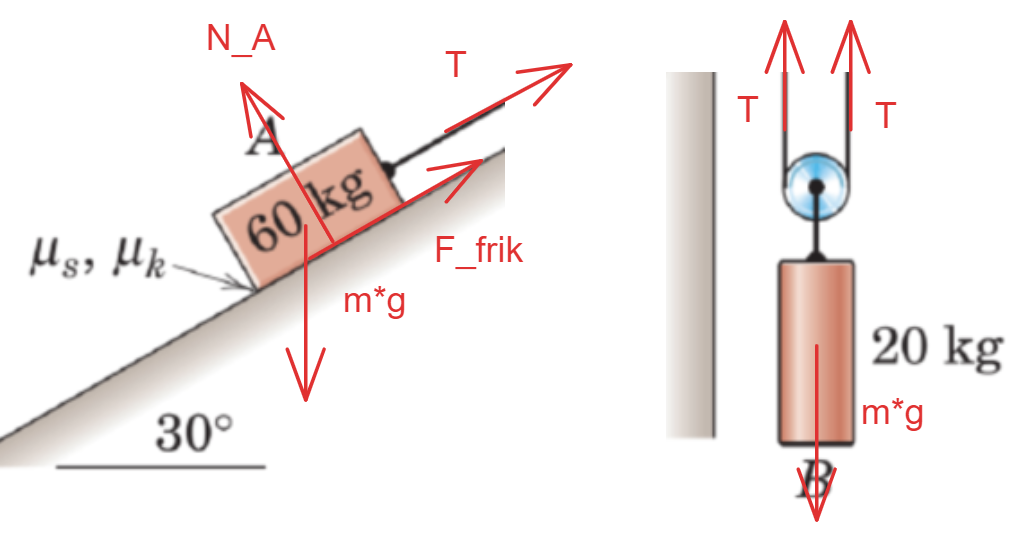

clear all
mu_s = 0.25;
mu_k = 0.2;
g = 9.81; %m/s^2

b) Begrund hvorfor legeme A bevæger sig nedad.

m_A = 60; % kg
m_B = 20; %kg
theta = 30; %
N_A = m_A * g * cosd(theta)

N_A = 509.7426

F_A = N_A * mu_s

F_A = 127.4356

G_A = m_A * g * sind(theta)

G_A = 294.3000

T_snot = m_B * g / 2

T_snot = 98.1000


F_x = G_A - F_A - T_snot

F_x = 68.7644

Kraften lod A glider ned med er således 68,76N og dermed starter lodet med at glide.

efter bevægelsensstat vil friktionskraften nu bruge $\mu_k$ i stedet og dermed blive reducerede.

c) Hvilken sammenhæng er der mellem accelerationerne af A og B?

Ligning A $\sum F_x$

F_A_k = N_A * mu_k

F_A_k = 101.9485

syms T a
F_x_eq = m_A * 2 * a == - G_A + F_A_k + T

$$F\_x\_eq = 120\,a=T-\frac{211492699288445}{1099511627776}$$

F_B_eq =  m_B * a == -2 * T + m_B * g

$$F\_B\_eq = 20\,a=\frac{981}{5}-2\,T$$

sol = solve([F_x_eq, F_B_eq], [T, a]);
T = vpa(sol.T, 5)

$$T = 105.35$$

a = vpa(sol.a, 5)

$$a = -0.72501$$

d) Beregn accelerationerne aA og aB samt snorkraften T.

T

$$T = 105.35$$

a_A = a * 2

$$a\_A = -1.4500229148691232694545760750771$$

a_B = a

$$a\_B = -0.72501$$

e) Beregn flytningen $s_A$ og hastigheden $v_A$ 10 sekunder efter frigørelsen.

syms t
v_A(t) = int(a_A, t);
v_A(10)

$$ans = -14.500229148691232694545760750771$$

s_A(t) = int(v_A(t), t);
s_A(10)

$$ans = -72.501145743456163472728803753853$$

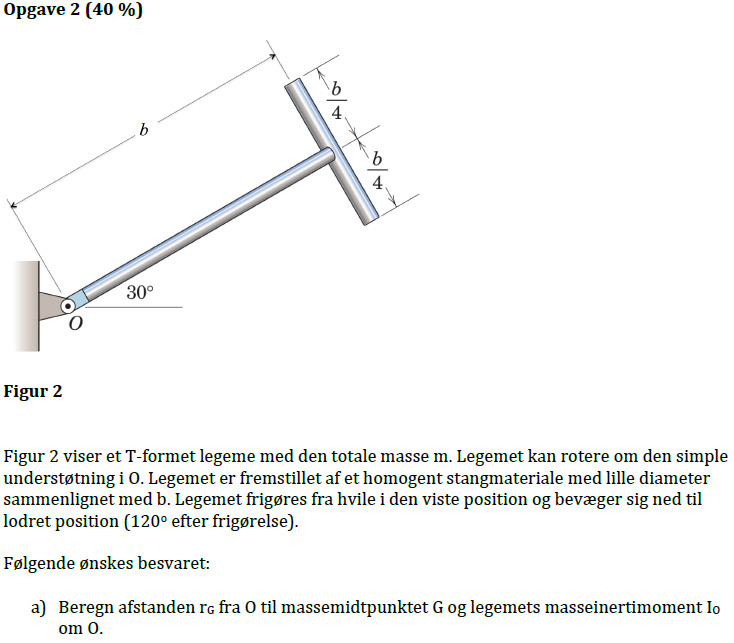

clear all
clc
syms m r_G l b

m_1 = 2/3 * m

$$m\_1 = \frac{2\,m}{3}$$

m_2 = 1/3 * m

$$m\_2 = \frac{m}{3}$$


r_G1 = b/2;
r_G2 = b;
r_G = (r_G1 * m_1 + r_G2 * m_2)/m

$$r\_G = \frac{2\,b}{3}$$

I_G1 = m_1 * b^2 / 3

$$I\_G1 = \frac{2\,b^{2}\,m}{9}$$

I_G2 = m_2 * (b/2)^2 / 12 

$$I\_G2 = \frac{b^{2}\,m}{144}$$

I_O = I_G1 + I_G2 + m_2 * b^2

$$I\_O = \frac{9\,b^{2}\,m}{16}$$

b) Beregn legemets vinkelhastighed i lodret position.

theta = 30

theta =     30


syms omega g
% g = 9.81 % m/s^2

h = r_G * sind(theta) + r_G

$$h = b$$


T_rot = 1/2 * I_O * omega^2;
V_pot = m * g * h;
eq = T_rot == V_pot

$$eq = \frac{9\,b^{2}\,m\,\omega^{2}}{32}=b\,g\,m$$


sol = solve(eq, omega);
omega = vpa(sol(1), 5)

$$omega = -\frac{1.8856\,\sqrt{g}}{\sqrt{b}}$$

32/9

ans =        3.5556


c) Optegn FBD og KD i lodret position.

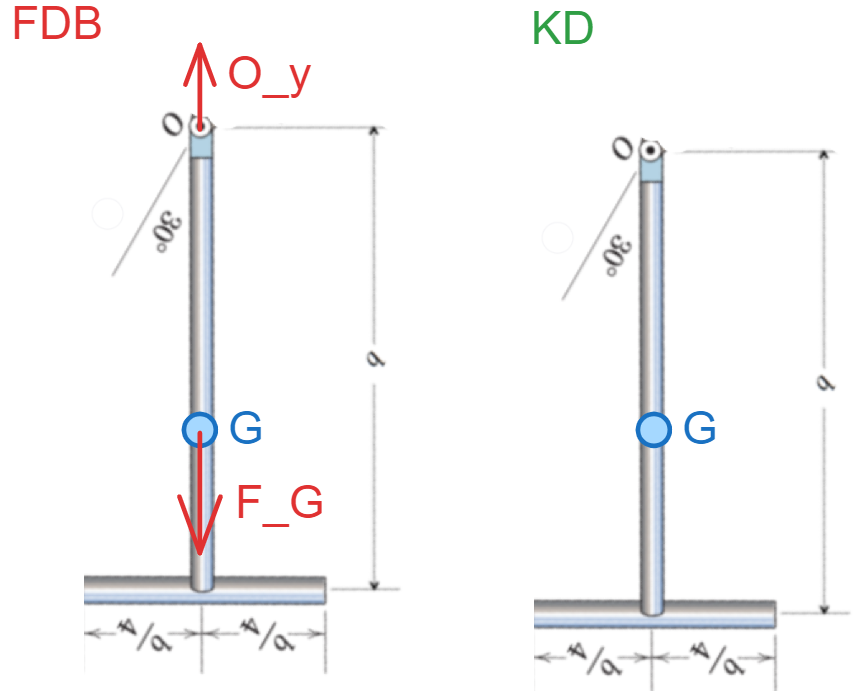

d) Beregn reaktionerne i O.

syms O_A
eq_OA = m * omega^2 * r_G == O_A - g * m

$$eq\_OA = 2.3703703703700275536390696637799\,g\,m=O_{A}-g\,m$$

solve(eq_OA, O_A)

$$ans = 3.3703703703700275536390696637799\,g\,m$$

91/27

ans =        3.3704


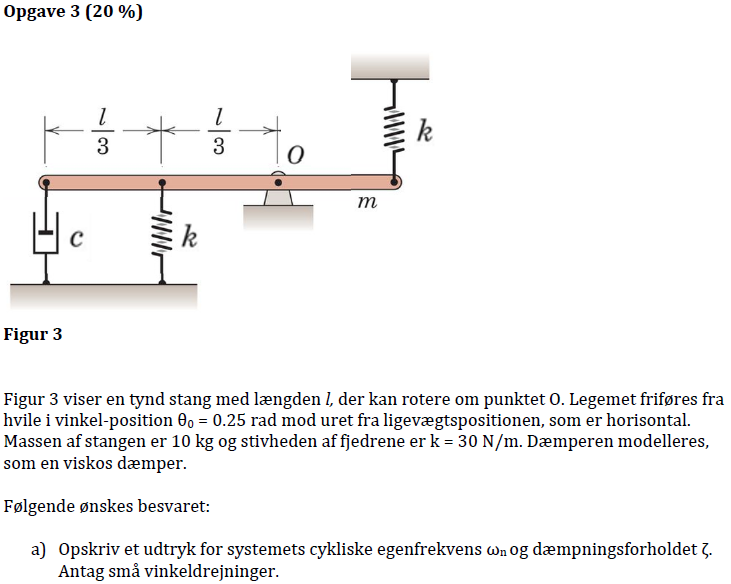

clear all
k = 30 * 2 %begge fjeder trækker ens %N/m

k =     60


theta_0 = 0.25; %rad
m_stang = 10;

syms c
w_n = sqrt(k/m_stang); %egensvingningen
zeta = c/(2 * m_stang * w_n); % viscous damping factor or damping ratio

b) Bestem dæmpningskoefficienten c så systemet er kritisk dæmpet.


eq = zeta == 1

$$eq = \frac{\sqrt{6}\,c}{120}=1$$

sol = solve(eq, c);
c = vpa(sol / 4, 5)

$$c = 12.247$$

c) Opskriv en funktion for vinkeldrejningen θ(t), hvor t er tiden fra frigørelsen og skitser funktionen.

syms A_1 A_2 t 
t_0 = 0;
theta_0 = 0.25;
theta_01 = 0;
theta = (A_1 + A_2 * t) * exp(-w_n * t)

$$theta = {\mathrm{e}}^{-\sqrt{6}\,t}\,\left(A_{1}+A_{2}\,t\right)$$

theta_1 = diff(theta, t)

$$theta\_1 = A_{2}\,{\mathrm{e}}^{-\sqrt{6}\,t}-\sqrt{6}\,{\mathrm{e}}^{-\sqrt{6}\,t}\,\left(A_{1}+A_{2}\,t\right)$$


[sol_A_1, sol_A_2] = solve([theta == theta_0, theta_01 == theta_1], [A_1, A_2]);
A_1 = subs(sol_A_1, t, t_0)

$$A\_1 = \frac{1}{4}$$

A_2 = subs(sol_A_2, t, t_0)

$$A\_2 = \frac{\sqrt{6}}{4}$$

theta(t) = (A_1 + A_2 * t) * exp(-w_n * t);
theta_1(t) = diff(theta(t), t)

$$theta\_1(t) = \frac{\sqrt{6}\,{\mathrm{e}}^{-\sqrt{6}\,t}}{4}-\sqrt{6}\,{\mathrm{e}}^{-\sqrt{6}\,t}\,\left(\frac{\sqrt{6}\,t}{4}+\frac{1}{4}\right)$$


t_max_eq = theta_01 == theta_1(t);
t_max = solve(t_max_eq, t)

$$t\_max = 0$$

theta_max = vpa(theta(t_max), 5)

$$theta\_max = 0.25$$

Således er den maximale forskydning 0,0864m = 86,4mm

Vi kontrollere med plots

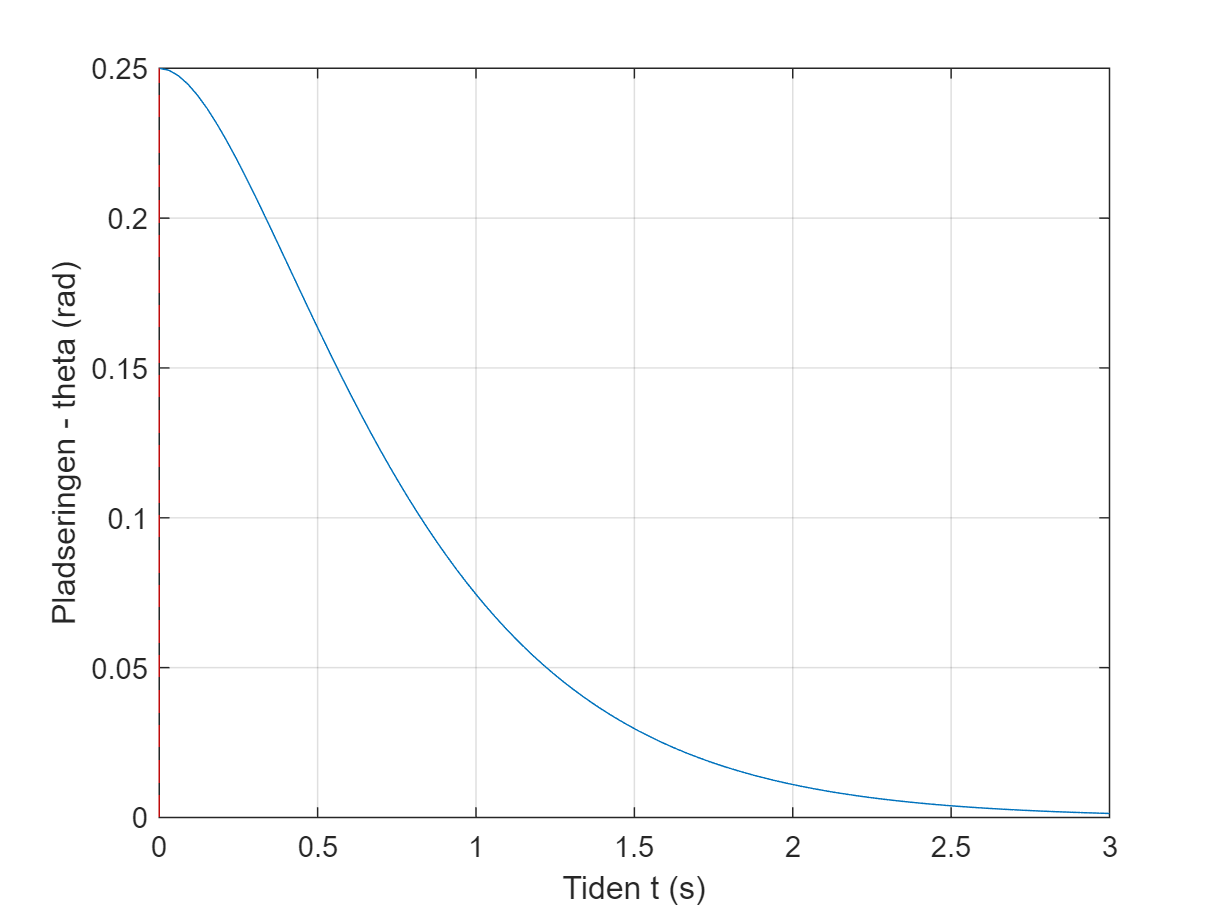

t_lin = linspace(0, 3,100);

plot(t_lin, theta(t_lin))
yline(0, '--')
xline(double(t_max), 'r--')
ylabel('Pladseringen - theta (rad)')
xlabel('Tiden t (s)')
grid('on')

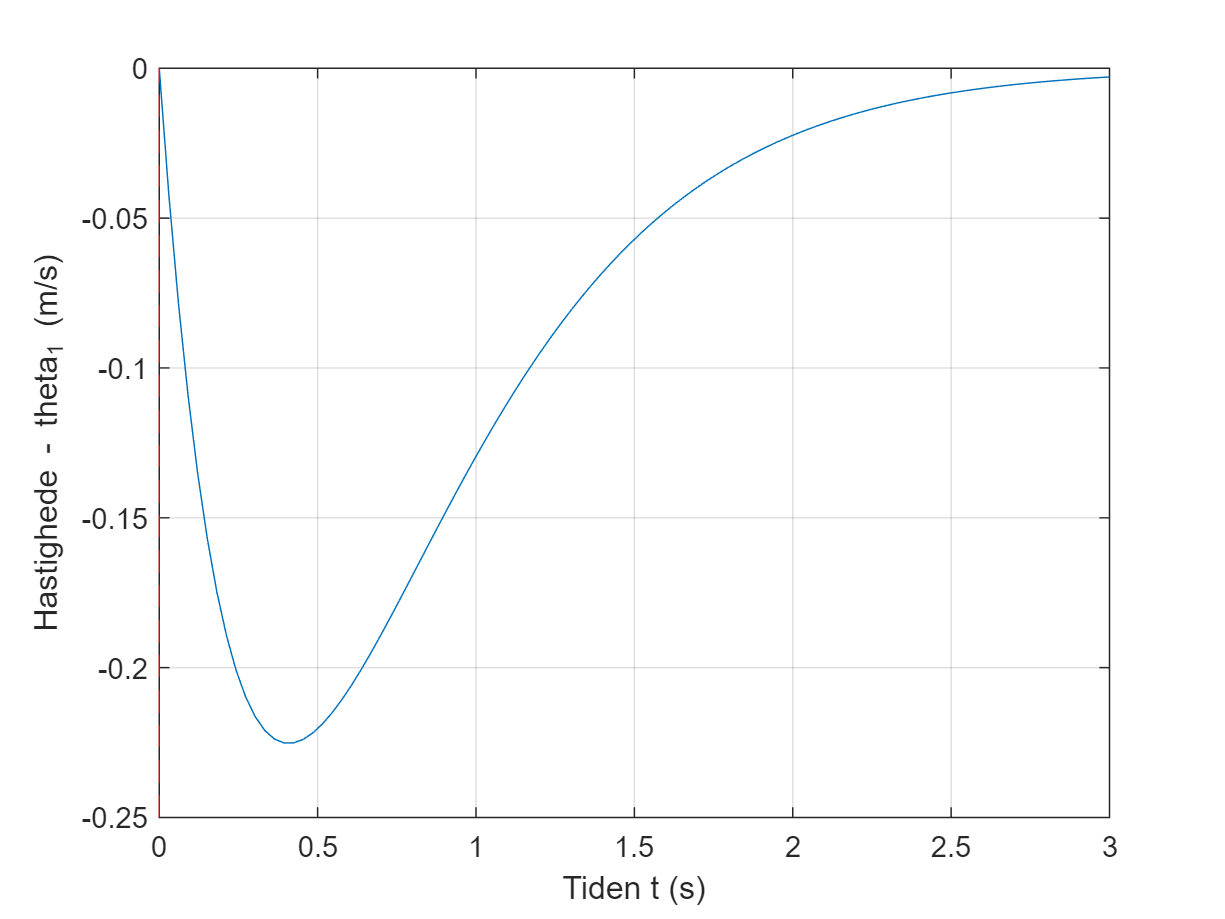

plot(t_lin, theta_1(t_lin))
yline(0, '--')
xline(double(t_max), 'r--')
ylabel('Hastighede - theta_1 (m/s)')
xlabel('Tiden t (s)')
grid('on')